# Plotting 

There are 4 main elements used to explore and visualise synaptic point clouds and analysis results:

- **Point clouds** : plot different groups of synapses as point clouds , representing each synapse as a point in 3D.

- **Voxels** : plot statistic per voxel (for example the number of gained synapses in a voxel, or the difference between the number of  lost and gained synapses)

- **DB-plane** : plot DB plane in 3D. 

- **Template** fish image : plot the image of the template fish to put everything else into the context.

Currently, only **Point clouds** work for single entries, that have not been registered. More possibilities on the way!  For convenience, there are some helper functions at the end of the file, you can change them if you would like. 

*This script is using **stu**,**syn** prodused by the **ImportSingleEntry**. 

## load utility functions

cd 'D:\Code\repos\synapse-redistribution\data_vizualization'
addpath('utils');

## Plot Point Clouds

Here is an example how to plot a point cloud that consists only of gained synapses. You need to set the fish (or group of fish) for which to plot synapses. 

Here we are plotting the synapses of the first fish in the Learners group only: 

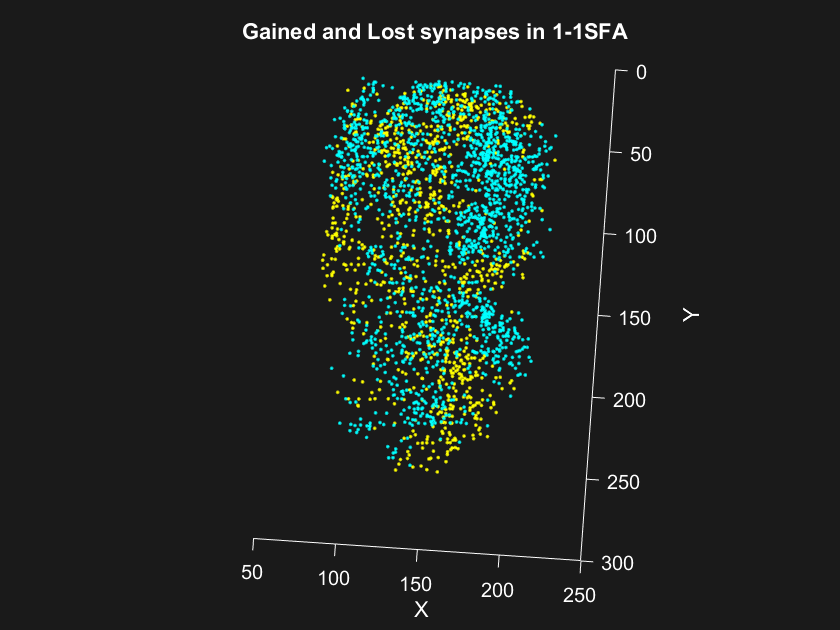

subject_id = stu.Id.Unassigned{1};
i_fish = stu.Unassigned(1);
% gained pointcloud 
pointCloud_ga = syn.gained.xyz{i_fish};
pointCloud_lo = syn.lost.xyz{i_fish};
figure;
% plot point clouds of the lost and gained synapses
plot_ptc(pointCloud_ga,'Color',[1 1 0],'MarkerSize',5);
hold on 
plot_ptc(pointCloud_lo,'Color',[0 1 1],'MarkerSize',5);

title(['Gained and Lost synapses in ',subject_id],'Color',[1 1 1]);
axisProperties

## Helper functions 

These are two functions: one sets the axis properties and another one draws a scale bar. They are helpful to save space when plotting, feel free to change them to your liking.

function axisProperties
% sets the axis limits, direction, labels and figure colors and default view
    xAxisLim = [0 510];
    yAxisLim = [0 350];
    zAxisLim = [-50 300];
    
    daspect([1 1 1])
    set(gca,'Zdir','reverse')
    set(gca,'Xdir','reverse')
    
    set(gca,'color',[0.1 0.1 0.1])
    set(gcf,'color',[0.1 0.1 0.1])
    set(gca,'XColor',[1 1 1],'YColor',[1 1 1],'ZColor',[1 1 1]);
    grid off
    box off
    
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    
% limis are commented out, uncomment if you'd like 
    %xlim(xAxisLim);
    %ylim(yAxisLim);
    %zlim(zAxisLim);
    
    % rotate to dorsal view:
    %view(180,90);
    
    % arbitrary angle in 3D:
    view([-165 15])

end
